# Code Fragment 2.5.1

### Numerical computation of Fourier transform using FFT

ts=1/16;
time_step = 0:ts:1; 
signal_time = sin(pi*time_step); 
fimesignal_expecct = 1/160;
N_min = ceil(1/(fimesignal_expecct*ts));
N_FFT = 2^(nextpow2(N_min)) %FFT size = the next power of 2 at least as big as Nmin

N_FFT = 4096

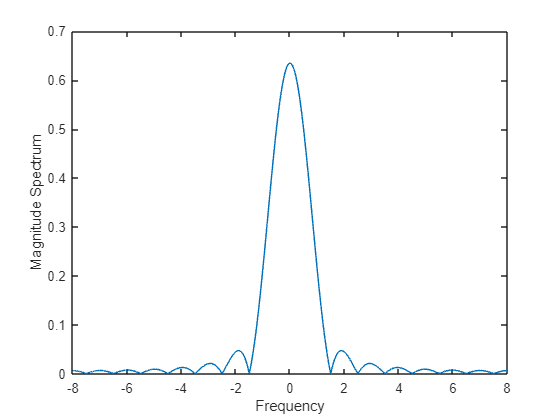

signalfreq_domain = ts*fft(signal_time,N_FFT);
signalfreq_domainc = fftshift(signalfreq_domain);
fs=1/(N_FFT*ts); %actual frequency resolution attained
freq = ((1:N_FFT)-1-N_FFT/2)*fs;
plot(freq,abs(signalfreq_domainc));
xlabel('Frequency');
ylabel('Magnitude Spectrum');

# Signals and Systems Computations using  Matlab

### Fourier Transform of signal.

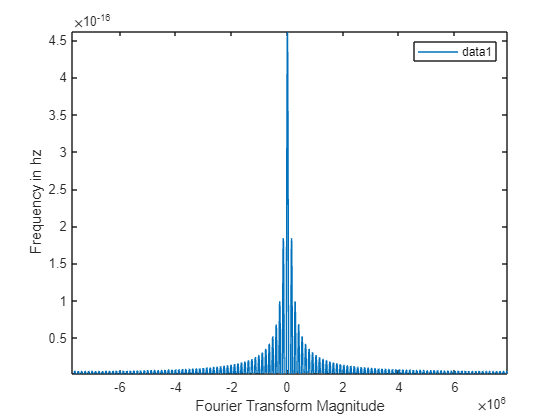

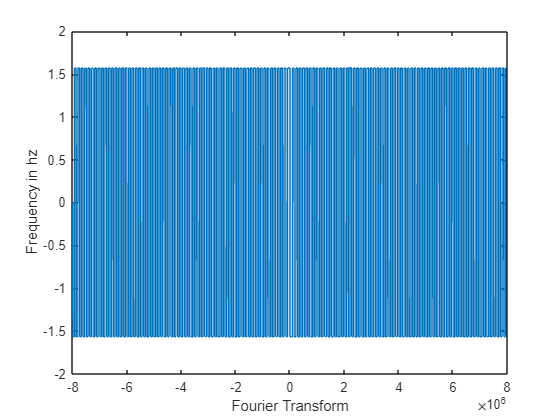

%Transform output
%Inputs
t=10^(-6);
dt = (1/16)*t;
time=-8*t:dt:8*t;
x = 3.*sinc(2*time-3) ;
t_start = -8*t;
df_expected = 1000;
contFT(x,t_start,dt,df_expected);

function [X,f,df] = contFT(x,tstart,dt,df_desired)

Nmin=max(ceil(1/(df_desired*dt)),length(x));
%choose FFT size to be the next power of 2
Nfft = 2^(nextpow2(Nmin));
X=dt*fftshift(fft(x,Nfft));
df=1/(Nfft*dt);
f = ((0:Nfft-1)-Nfft/2)*df; %same as f=-1/(2*dt):df:1/(2*dt) - df
%phase shift associated with start time
X=X.*exp(-j*2*pi*f*tstart);
figure(1);
plot(f,X);
xlabel('Fourier Transform Magnitude');
ylabel('Frequency in hz');
figure(2);
plot(f,angle(X));
xlabel('Fourier Transform');
ylabel('Frequency in hz');
end